% I'll start with simulating a data matrix.
n_timepoints = 5;
n_observations = 50;
data_matrix = zeros(n_observations, n_timepoints);
sigma2 = 0.5;
rho = 0.9;

for i=1:n_observations
    first_value = normrnd(0,sqrt(sigma2),1);
    data_matrix(i,1) = first_value;
    for j = 2:n_timepoints
        data_matrix(i,j) = rho*data_matrix(i,j-1) + normrnd(0,sqrt(sigma2),1);
    end
end


[U, Lambda, ~] = svd(cov(data_matrix));
A = (eye(n_timepoints) - U)/(eye(n_timepoints) + U);

solve_this = @(a) (ar1_constraint(a));
options = optimoptions('fsolve','Display','none','TolFun', 1e-10);
initial = collapseParameters(A,Lambda);
% initial = [-5, log(0.1), log(0.4), log(1.6), log(1.5), log(2.3), log(1.5), log(2.4), log(2.1),...
%     log(1.2), log(1.25), log(1.3), log(0.6), log(0.7),...
%     log(0.5), log(0.4), log(0.3), ...
%     -2.5];
% initial = [-2, log(1), log(2), log(1), log(0.9), log(0.7), log(0.4), -2];
initial_guess = fsolve(solve_this, initial, options)

initial_guess =     0.7407
    0.7188
    0.7216
   -0.6909
    0.7883
    0.3617
    4.0298
    3.6016
   -0.4869
   -0.9019



num_iters = 200;
burn_in = 1;
proposal_scale = 8e-4

proposal_scale = 8.0000e-04


ll_function = @(x) ll_density(x, data_matrix);
constraintFunc = @(x) (ar1_constraint(x));
dConstraintFunc = @(x) (dar1_constraint(x));

warning('off');
[samples, accepts] = runConstrainedMH(num_iters, burn_in, ...
    proposal_scale, initial_guess, ll_function, ...
    constraintFunc, dConstraintFunc);

MH ratio is: -2.229192e+01.
MH ratio is: 1.398427e+01.
MH ratio is: -4.612729e+02.
MH ratio is: -3.935462e+01.
MH ratio is: -4.908795e+00.
MH ratio is: -4.897999e+01.
MH ratio is: 2.315107e+01.
MH ratio is: 4.783303e+00.
MH ratio is: 1.034370e-02.
MH ratio is: -3.145457e+00.
MH ratio is: -3.275447e+00.
MH ratio is: -2.644122e+00.
MH ratio is: -5.383916e+01.
hey
MH ratio is: -Inf.
hey
MH ratio is: -2.814812e+00.
MH ratio is: -2.886033e+00.
MH ratio is: -3.757779e+01.
hey
MH ratio is: -Inf.
hey
MH ratio is: -4.370308e+01.
MH ratio is: -4.452922e+00.
MH ratio is: -1.109514e+02.
MH ratio is: -1.675072e+02.
MH ratio is: -7.086376e-01.
MH ratio is: -2.323295e+00.
MH ratio is: -4.083889e+00.
MH ratio is: -5.798435e-01.
MH ratio is: -5.591926e+01.
MH ratio is: -1.738661e+04.
MH ratio is: -3.105859e+02.
MH ratio is: -2.048898e+00.
MH ratio is: -1.687169e+00.
MH ratio is: -3.105236e+00.
MH ratio is: -2.287612e+00.
MH ratio is: 4.155649e+00.
MH ratio is: 1.192206e+00.
MH ratio is: -2.671883e-01.


mean(accepts)

ans = 0.1100

save("MH_ar1_Draws.mat",'samples');

## Use the samples to calculate values for rho and sigma2:

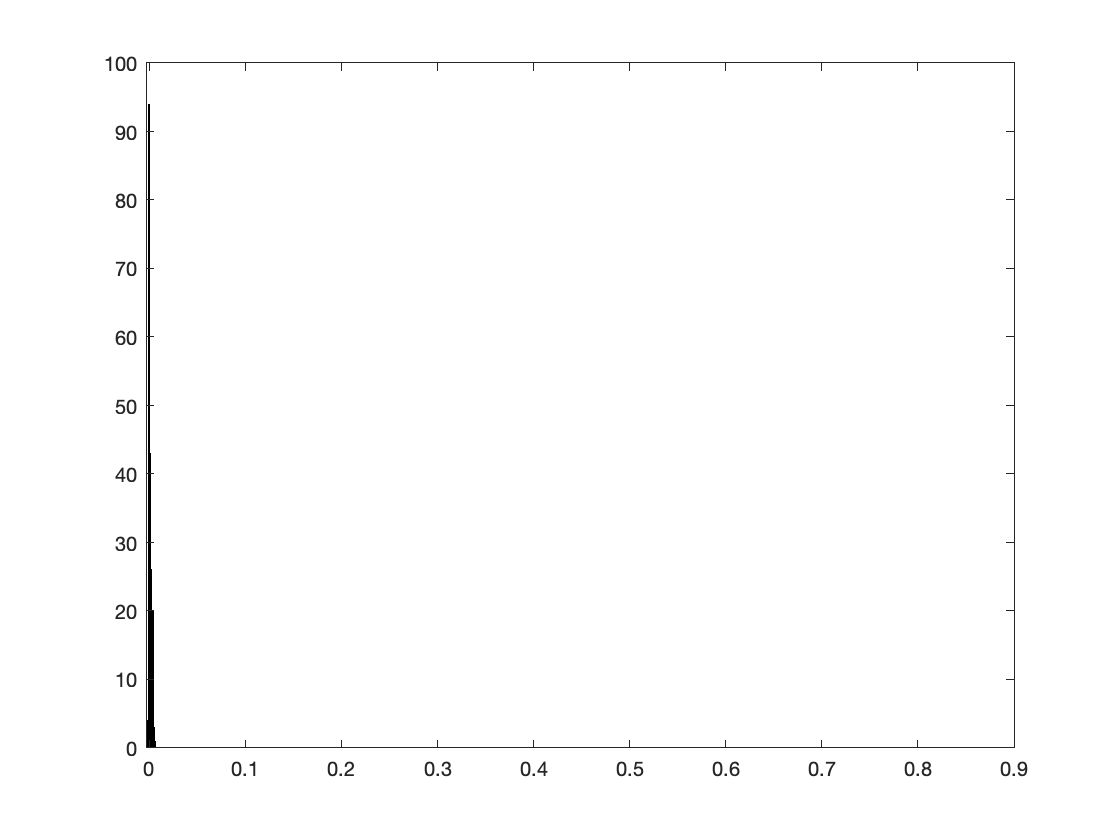

samples = load("MH_ar1_Draws.mat").samples;
[~,num_of_samples] = size(samples);
rhos = zeros(1,num_of_samples);
s2s = zeros(1,num_of_samples);

for i=1:num_of_samples
    [A, Lambda] = uncollapseParameters(samples(:,i));
    U = (eye(n_timepoints) - A)/(eye(n_timepoints) + A);
    sigma = U*(Lambda.^2)*(U');
    rhos(i) = sigma(1,2)/sigma(1,1);
    s2s(i) = sigma(1,1)/(1 - (sigma(1,2)/sigma(1,1)).^2);
end

histogram(rhos);
hold on
xline(rho);
hold off

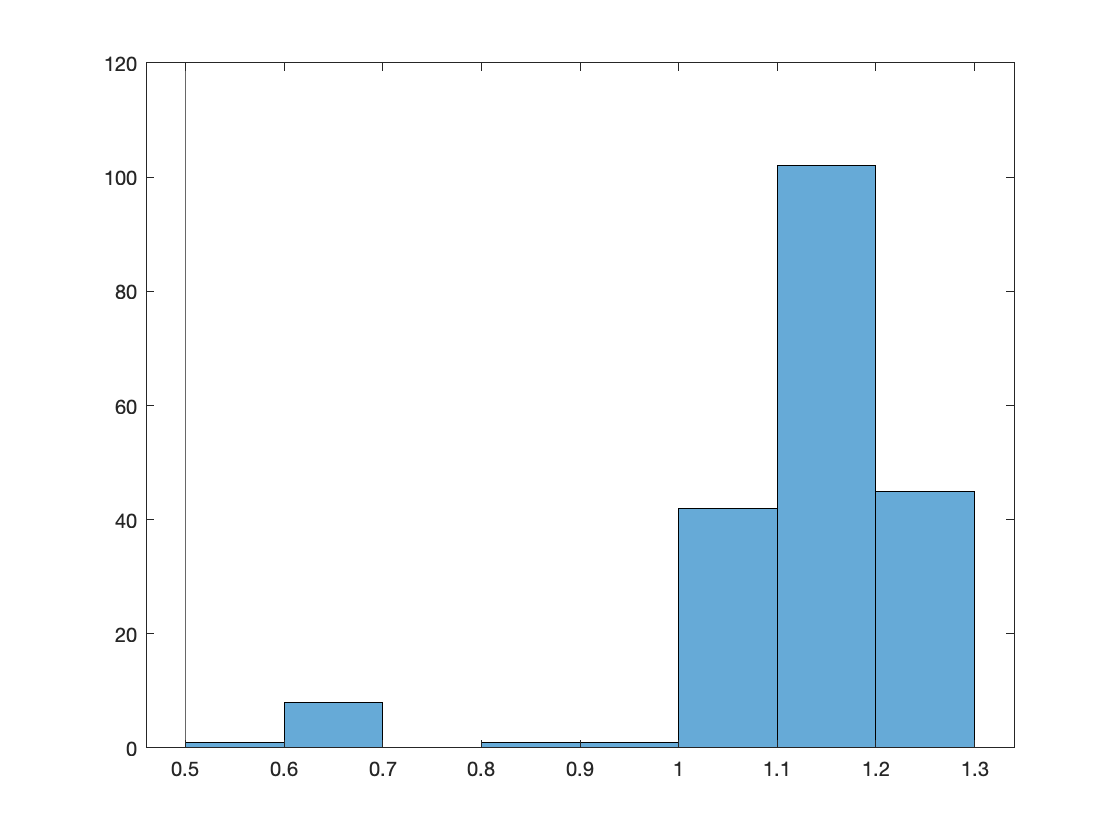


histogram(s2s);
hold on
xline(sigma2);
hold off